# Introduction to "Tensor Networks" tutorial materials

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr/)

## Installation of tutorial materials

**1. Install MATLAB. **All the coding tutorial materials for this lecture course will run on MATLAB. Also, the final exam problems are coding tasks building upon the codes developed during the tutorials. So we ask students to have MATLAB installation at their laptops. During this course, only the core MATLAB will be used, without requiring additional toolboxes.

As a member of Seoul National University (SNU), Korea Advanced Institute of Science and Technology (KAIST), or Korea University, you can use a campus license for your university. You need to first sign up at [MathWorks website](https://www.mathworks.com/), using your university e-mail. Then you can download all releases of MATLAB for Windows, MacOS, and Linux from the website. Choose any release from recent years.

**2. Create working directory** on your laptop to store the materials. Let's call this directory `TN`. (TN for "tensor networks".) While the TN directory can be created anywhere you want, we recommend creating it directly under the default working directory of MATLAB for organizational reasons. If you don't know what the default directory is, first start MATLAB. Then type the following in the "Command Window":

restoredefaultpath % restore the default setting of path
path % show the current path

Many lines will show up, but only the first line is needed by now. This first line indicates the path of the default working directory. For Mac and Linux installations, the default installation setting is `~/Documents/MATLAB` . Then create a directory named `TN` under this. One way to create a directory is to use MATLAB, by typing in the command window:

mkdir ~/Documents/MATLAB/TN

The following instruction assumes that the TN directory is at `~/Documents/MATLAB/TN`.

And create a subdirectory `MyWork` under the TN directory, to place the functions and scripts you compose during the tutorials.

mkdir ~/Documents/MATLAB/TN/MyWork

**3. Download the tutorial materials** from [the GitHub repository](https://github.com/ssblee/TensorNetworks2022) in either way:

(1) From the main page, click "Code" (green button) and then click "Download ZIP" (see a screenshot below). All the materials will be bundled into a .zip file. Then unzip the .zip file to fill the TN directory.

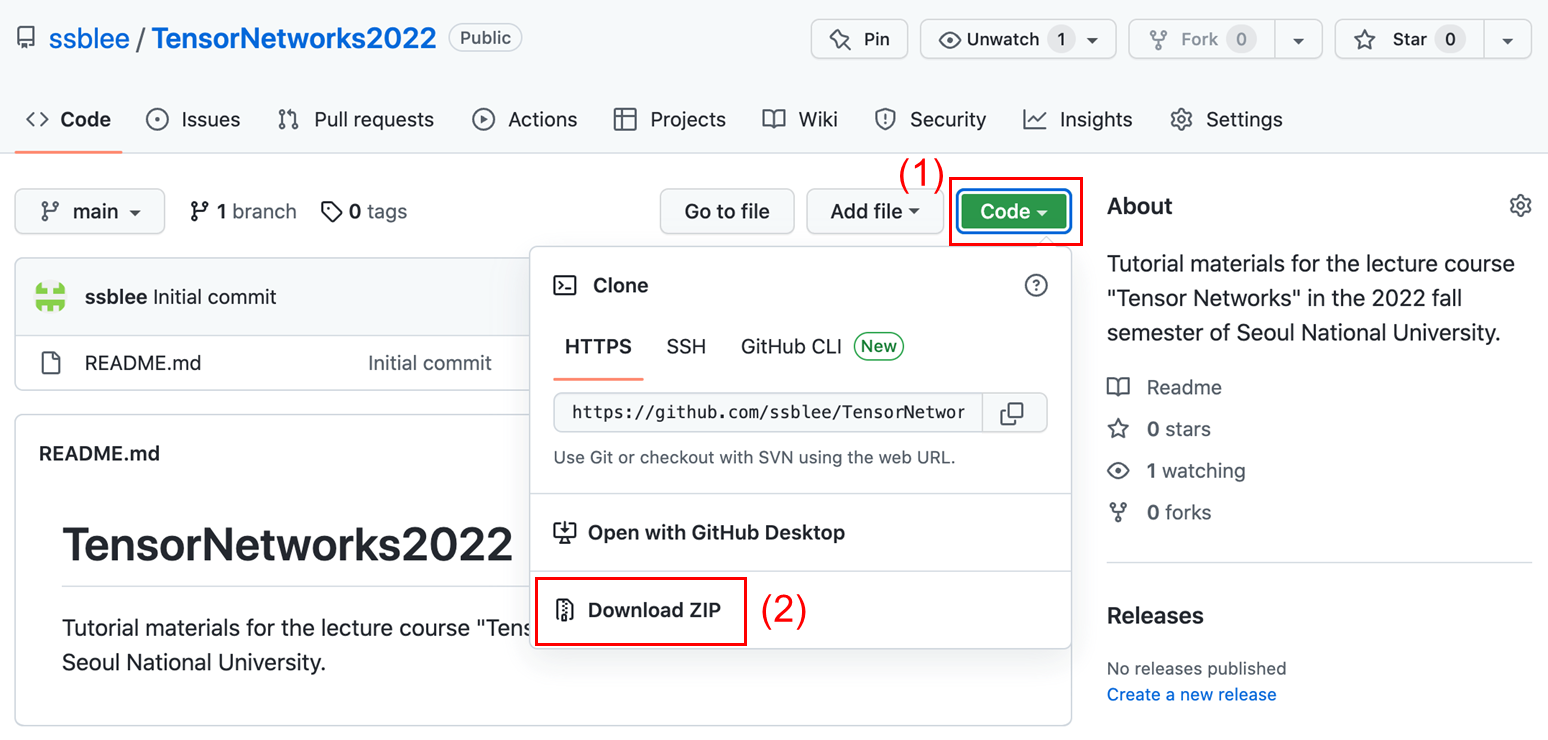

(2) If you know how to use Git, then you can clone the repository to the TN directory on your laptop. This way requires a prior knowledge, but will be more convenient since the GitHub repository will be regularly updated during the course. See **6. Regularly update the TN directory** below for details.

After taking (1) or (2), your TN directory ready for the first class would look like:

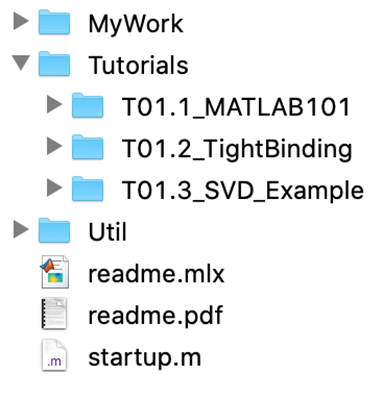

**4.** **Set path.** To let the codes run by MATLAB, you should add the TN directory and its sub-directories into the path. It can be done by using the startup script, `startup.m`, which is placed directly under the TN directory. Change the current directory to be the TN directory, by (i) double-clicking the TN directory in the "Current Folder" window, or by (ii) typing in the "Command Window":

cd ~/Documents/MATLAB/TN

Then run `startup.m`, by (i) typing the script name (without extension .m) in the command window,

startup

or by (ii) opening `startup.m` in the "Editor" window (via double-clicking the file from the "Current Folder" window) and running the script (via clicking on "Run" button on top of the Editor window).

**Note:** We do **not** recommend using the "Set Path" button in the `Home` menu bar of MATLAB, or to define `pathdef.m` via `savepath` function. When you are working on multiple projects with MATLAB, it is necessary to set the path differently for different projects to avoid conflicts among the functions and files associated different projects. But "Set Path" or `pathdef.m` defines the default path for all projects.

**5.** **Create a shortcut.** When a new MATLAB session starts, the path is reset to the default. Thus, it is necessary to run `startup.m` for every new MATLAB session. To simplify this task, you can use a "Favorite" as a shortcut. Click "Home", then "Favorites", then "New Favorite" (see a screenshot below).

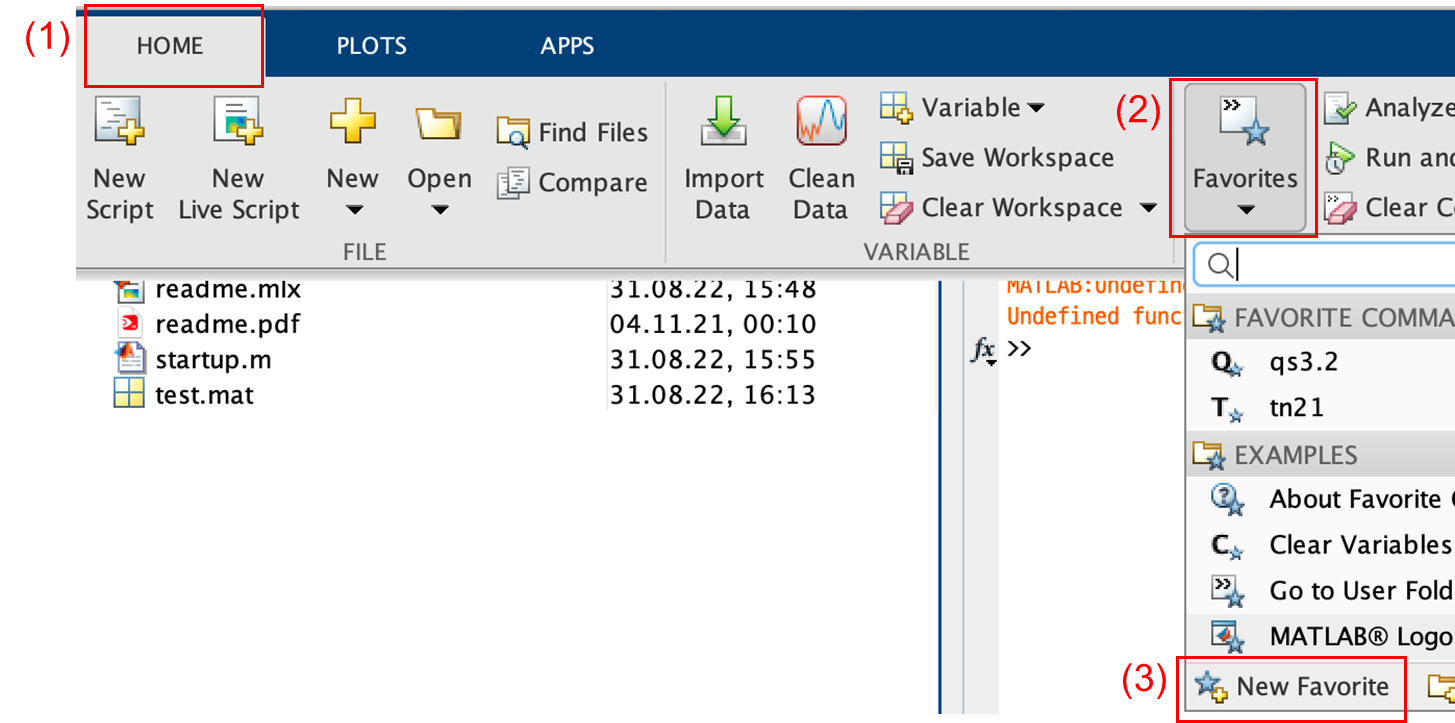

Then a window appears. Fill the blanks and tick checkboxes as below. And click "Save".

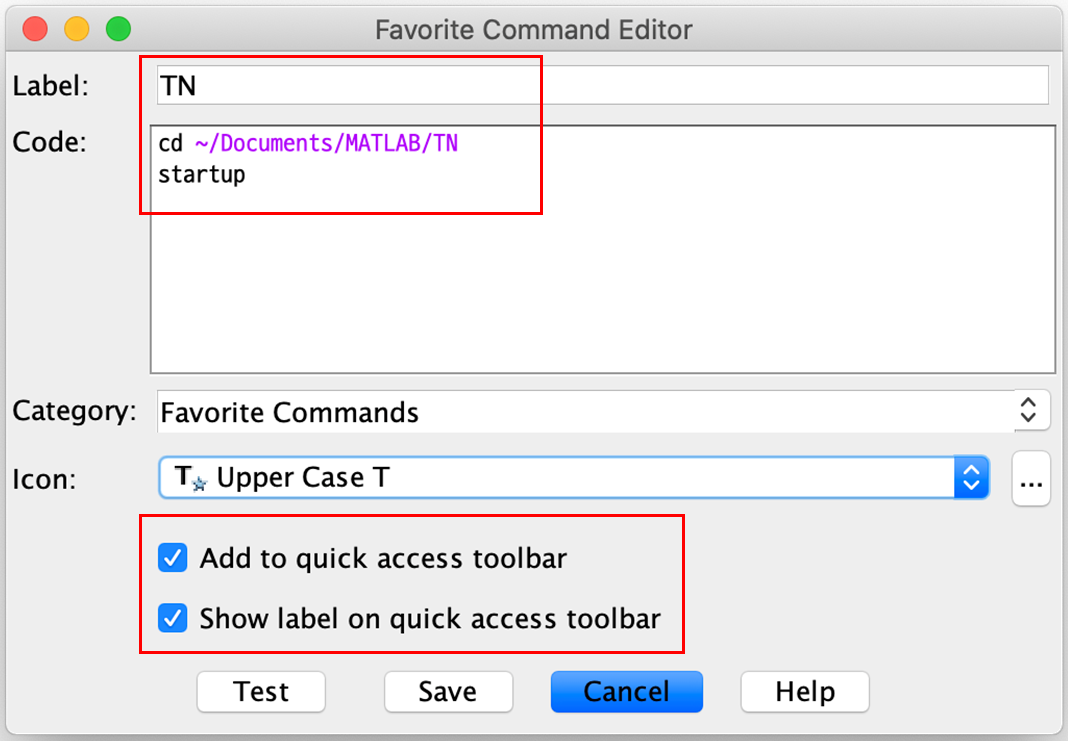

Then a new icon "TN" will appear next to the arrow-and-plus icon you clicked. From now on, you can simply click the new icon after launching a MATLAB session, to set the path.

**6. Regularly update the TN directory.** The instructor will update the GitHub repository as the course progresses, so that it contains new and updated functions and Live Scripts for the upcoming tutorials. Also, the repository will be occasionally updated to fix errors and improve explanations. Therefore, please update your TN directory with the latest version of the repository in regular basis!

If you choose to use Git to obtain the materials (see **3. Download the tutorial materials** above), then your Git client (e.g., Sourcetree) will notify you about the updates and you will need to just "pull" the latest "commit". If you choose to simply download a .zip file, then you will need to download the lastest .zip file and overwrite your TN directory. In this case, the size of the .zip file will increase after every class (as new tutorial files will be included), so it will take more time to download.

## Structure of the TN directory

There are several sub-directories in the TN directory, which are designed as follows:

`MyWork`: This directory should contain the codes generated by yourself. **Please do not put your own codes in the other directories**, since the other directories will be regularly updated by the instructor. In other words, the `MyWork` directory is not included in the GitHub repository.

`Tutorials`: This directory should contain the demonstrations and exercises for each tutorial session. Each sub-directory of `Tutorials` contains a triplet of files with extensions .mlx, .pdf, and .m.

- **.mlx**: The MATLAB Live Script is the main tutorial material that comprises demonstration, explanation, and exercise problems. The .pdf and .m files are conversions from the .mlx file. You can directly run the codes in the .mlx file and see the results together with the accompanying explanation (figures, equations, etc.).

- **.pdf**: A printable version of the tutorial material.

- **.m**: The standard MATLAB script, which is a plain text file. It can be used as an alternative to the .mlx file, since for some cases running .mlx can be very slow. (MATLAB Live Scripts are not designed for heavy calculations!)

`Util`: General utility functions. For example, `tic2` and `toc2` measure real/CPU time lapse, and `chkmem` measures memory occupation of the MATLAB session.

Other directories, e.g., `NRG`, and `DMRG,` will be also added as the course progresses. They will contain the functions for e.g., the numerical renormalization group (NRG) and the density-matrix renormalization group (DMRG), respectively.

## Trouble shooting

- **Undefined function or variable?**: One of the most common problems encountered by beginners is the path problem. Please check whether your TN directory (including `startup.m`) is up-to-date, except your own sub-directory `MyWork`. Then run `startup.m` again.

- **I don't know anything about MATLAB!**: Don't worry. There will be a very introductory tutorial material on MATLAB basics.

- Any other problems? Please contact [Seung-Sup Lee](mailto:sslee@snu.ac.kr) (instructor) and [Il Young Lee](mailto:ss900824@snu.ac.kr) (TA). We would welcome questions and comments, both during classes and at other times.